clc;clear;close all;format compact;

# Lektion 1

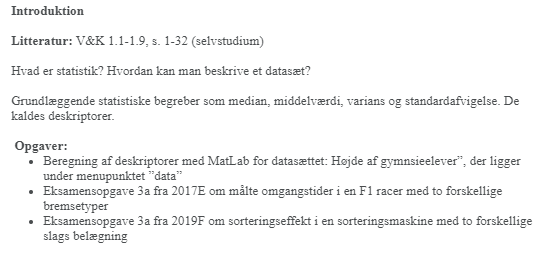

clear

height = [167 162 170 184 162 183 182 160 183 167 188 173 166 169 172 172 160 163 151 169 167 173 179 182 186];

% Deskriptorer
mean(height)

ans = 171.6000

me = median(height)

me = 170

st = std(height, 1)

st = 9.4403

var = var(height, 1)

var = 89.1200

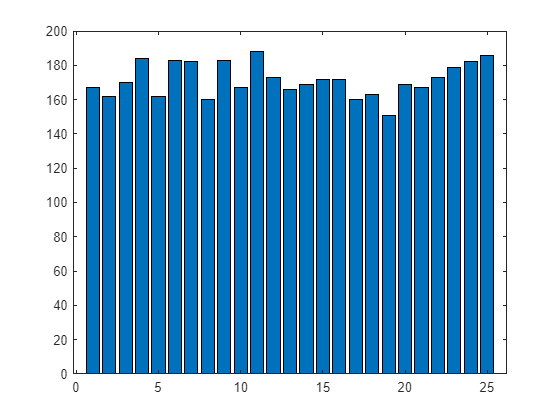


bar(height)

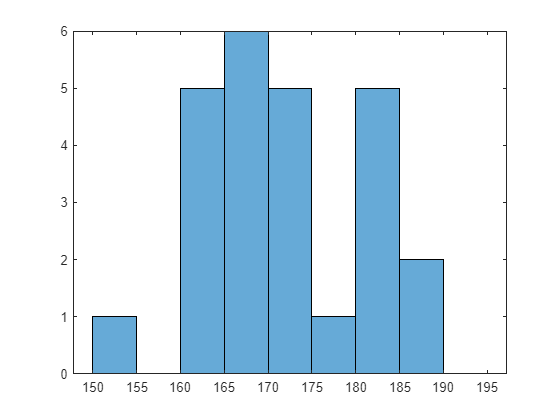

histogram(height, [150:5:195])

## 3a 2017E

clear

data = xlsread("Data_M4STI1_2017E.xlsx", 'K:L');

Br = data(:, 1)

Br =    92.5320
   92.8750
   94.4790
   92.1390
   93.7850
   93.3090
   92.7660
   91.9430
   92.7160
   92.9130


Cl = data(:, 2)

Cl =    90.2740
   95.8780
   92.0530
   94.2860
   89.8920
   94.6340
   95.8220
   95.3620
   90.3720
   93.9600



% Deskriptorer for Cl
[middel_cl, med_cl, varians_cl, stdafv_cl] = deskriptorer(Cl)

middel_cl = 92.9125

med_cl = 92.5085

varians_cl = 6.4956

stdafv_cl = 2.5487


% Deskriptorer for Br
[middel_br, med_br, varians_br, stdafv_br] = deskriptorer(Br)

middel_br = 92.7978

med_br = 92.8205

varians_br = 0.6389

stdafv_br = 0.7993


min(Cl), max(Cl)

ans = 87.9030

ans = 98.2730

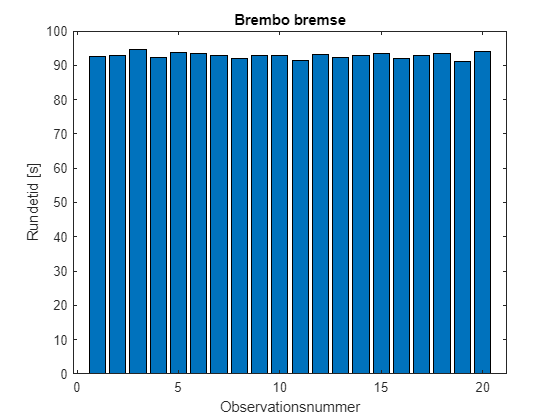

% Plot
bar(Br)
title("Brembo bremse"), xlabel("Observationsnummer"), ylabel("Rundetid [s]")

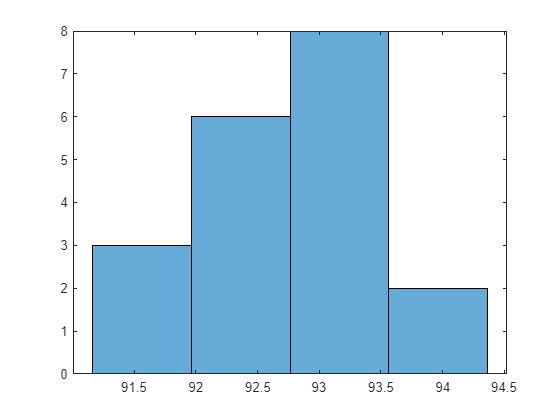


histogram(Br, [min(Br):stdafv_br:max(Br)])

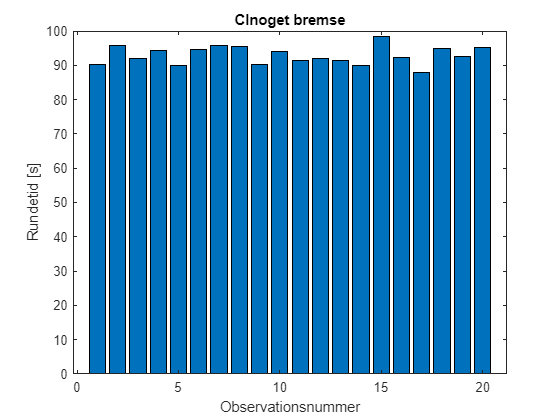


% Plot
bar(Cl)
title("Clnoget bremse"), xlabel("Observationsnummer"), ylabel("Rundetid [s]")

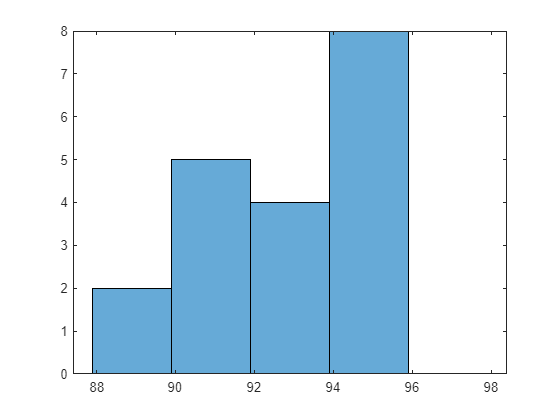


histogram(Cl, [min(Cl):floor(stdafv_cl):max(Cl)])

## 3a 2019F

clc; clear;

data = xlsread("Data_M4STI1_2019F.xlsx", 'E:F');


% Oprindelig data
effop = data(:, 2);
[middel, med, varians, stdafv] = deskriptorer(data)

middel =    80.6875   80.3958


med =    81.1500   80.4500


varians =    30.5528    6.3296


stdafv =     5.5275    2.5159


% Ny data
effny = data(:, 1);
[middel, med, varians, stdafv] = deskriptorer(data)

middel =    80.6875   80.3958


med =    81.1500   80.4500


varians =    30.5528    6.3296


stdafv =     5.5275    2.5159


# Funktioner

function [middel, med, varians, stdafv] = deskriptorer(data)

middel = mean(data);
med = median(data);
varians = var(data, 1);
stdafv = std(data, 1);



end